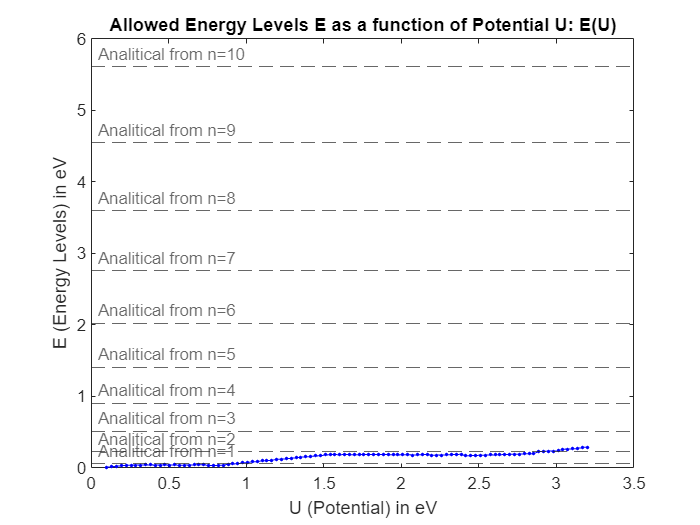

% Constants definition
m_eff=0.067; % Ratio of the mass
m_e = 9.10938356e-31; % electron rest mass, in kg
m=m_eff * m_e; % Effective mass of the electron
hbar = 1.0545718e-34;   % Planck's constant over 2*pi, in J*s
a = 10e-9;      % Potential well width
eV = 1.602176634e-19; % Joule per eV

U_min = 0.1;
U_max = 3.2;
num_points = 100;
% Predefined U values in Joules (easier to calculate)
U_values = linspace(U_min, U_max, num_points);
%[(0.1), (0.2), (0.8), (1.6), (3.2)];
% Results from exercise (a) in eV
analitical_results=[0.0561239038617234,0.224495615446894,0.505115134755511,0.897982461787575,1.40309759654309,2.02046053902204,2.75007128922445,3.5919298471503,4.5460362127996,5.61239038617234];

% Preallocate the array for energy levels
E_levels = zeros(1, length(U_values));

% Function to solve for E as a function of U
solveE = @(E, U) tan(a*sqrt(2*m*E/hbar^2)) - 2*sqrt(E/U*(1 - E/U_0))/(2*E/U - 1);

% Handle for when tan goes to infinite - remove the warnings
options = optimset('Display', 'off', 'TolX', 1e-6);

% Loop over each potential value to solve for E
for i = 1:length(U_values)
    U = U_values(i) * eV;
    
    % Define an anonymous function for the current U
    currentFun = @(E) solveE(E, U);
    
    % Make sure the initial guess is in a physically meaningful in the range
    E_guess = U * 0.1;  % Start with a guess of 10% of U
    
    try
        % Finds the root numerically
        [E_root, ~, exitflag] = fzero(currentFun, E_guess, options);
        
        % Only accept the root if fzero has converged and the root is within the expected range
        if exitflag == 1 && E_root < U
            E_levels(i) = E_root / eV; % Put back the value in eV
        else
            E_levels(i) = NaN; % Not a number if it did not converge or is out of range
        end
    catch
        % If an error occurred, set the energy level to NaN
        E_levels(i) = NaN;
    end
end

% Plot the result
figure;
plot(U_values, E_levels, 'b.-');
% Add a horizontal line for the analytical results (placeholder value)
for j = 1:length(analitical_results)
    yline(analitical_results(:,j), '--', append('Analitical from n=',int2str(j)), 'LabelHorizontalAlignment','left', 'HandleVisibility', 'off');  % Replace '1' with the actual analytical result value
end
xlabel('U (Potential) in eV');
ylabel('E (Energy Levels) in eV');
title('Allowed Energy Levels E as a function of Potential U: E(U)');

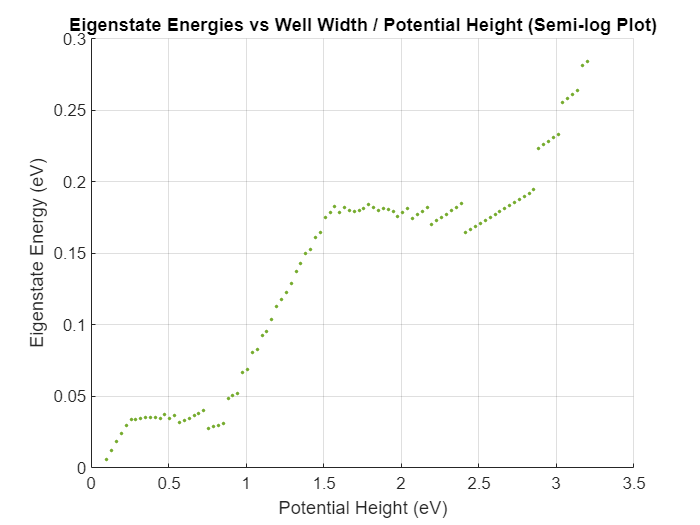


% Create a semi-log plot
figure;
hold on;
for n = 1:num_states
    semilogy(U_values, E_levels, '.');
end
xlabel('Potential Height (eV)');
ylabel('Eigenstate Energy (eV)');
title('Eigenstate Energies vs Well Width / Potential Height (Semi-log Plot)');
grid on;